# Twizy Class - Basics of Image Processing

Vasu Bhog 03/06/2018

## SAMPLING AND FILTERING

## PART 1

%%%% Load and display the boat.png and elaine.jpg images
boat = imread('Twizy_Matlab/ImagesTP/boat.png');
elaine = imread('Twizy_Matlab/ImagesTP/elaine.jpg');
figure;imshow(boat);title('Boat');
I_boat = im2double(boat); 
figure;imshow(elaine);title('Elaine');
I_elaine = im2double(elaine);

## SAMPLING AND FILTERING

## PART 2

%%%% Display the magnitude and phase of their FFT
boat_f2 = fft2(boat);
fboat = fftshift(boat_f2);
logmodboat = log(abs(fboat));
figure;imagesc(logmodboat);colormap gray; title('Boats Magnitude');
phaseBoat = angle(fboat);
figure;imagesc(phaseBoat);colormap gray; title('Boats Phase');

elaine_f2 = fft2(elaine);
felaine = fftshift(elaine_f2);
logmodelaine = log(abs(felaine));

figure;imagesc(logmodelaine);colormap gray; title('Elaine Magnitude');
phaseElaine = angle(felaine);
figure;imagesc(phaseElaine);colormap gray; title('Elaine Phase');

## SAMPLING AND FILTERING

## PART 3

%%%% Synthetize by inverse FFT two new images where the magnitudes 
%%%% and phases of the two original images are inverted
ImageInv1 = abs(fboat).*(cos(angle(felaine)) + 1j*(sin(angle(felaine))));
imageBack1 = ifft2(ImageInv1);
figure;imagesc(imageBack1);colormap gray; title('Boats Magnitude and Elaine Phase');

ImageInv2 = abs(felaine).*(cos(angle(fboat)) + 1j*(sin(angle(fboat))));
imageBack2 = ifft2(ImageInv2);
figure;imagesc(imageBack2);colormap gray; title('Elaine Magnitude and Boat Phase');

## SAMPLING AND FILTERING

## PART 4

%%%% We wish to divide by 4 the size of the original images:
%%%% Subsample the images by retaining one pixel out of two
%%%% Apply the 3×3 filter:[1 2 1]t[1 2 1]before subsampling, and compare

h = [1 2 1]' * [1 2 1]/16;

IBoatSsech = boat(1:2:end, 1:2:end);
figure();imshow(IBoatSsech);title('Boat sub sample');

BoatFilter = imfilter(boat, h);
figure, imshow(BoatFilter)
title('Boat with filter');
IboatFilSesh = BoatFilter(1:2:end, 1:2:end);
figure();imshow(IboatFilSesh)
title('Boat with filter and sub sample');

IelaineSsech = elaine(1:2:end, 1:2:end);
figure();imshow(IelaineSsech);title('Elaine sub sample');

ElaineFilter = imfilter(elaine,h);
figure;imshow(ElaineFilter)
title('Elaine with filter');
IelaineFilSesh = ElaineFilter(1:2:end, 1:2:end);
figure();imshow(IelaineFilSesh)
title('Elaine with a filter and sub sample');

## Histogram AND Thresholding

## Binarization PART 1

imhist(boat);title('Histogram of Boat');
binaryBoat = boat>140;
figure;imshow(binaryBoat);title('Binarize of Boat');

grayBoat = graythresh(boat);
binaryBoat = boat>(grayBoat*255);
figure;imshow(binaryBoat);title('GrayThresh of Boat');

## Histogram AND Thresholding

## Color Binarization - Part 2

pions = imread('Twizy_Matlab/ImagesTP/pions.jpg');
I_pions = im2double(pions);
figure;imshow(pions);title('Pions');
hsvPions = rgb2hsv(pions);
huePoins = hsvPions(:,:,1);
figure;imhist(huePoins);title('Histogram of Pions Hue');
binaryPoins = (huePoins>.1 & huePoins < .2) |  (huePoins > 0.95);
%huePoins (.1 - .2 = Yellow Tokens) 
%huePoins (>.95 Red Tokens)
ColorTokens= I_pions.*repmat(binaryPoins,1,1,3);
figure;imshow(ColorTokens);title('Binarize of Poins with Color');

## Erosion - dilation

structPions = strel('disk',4,0); %Structuring element
erodePions = imerode(binaryPoins,structPions); %Erode first
figure;imshow(erodePions);title('Erode Pions');
%figure;imshow(binaryPoins);title('binary poins');
dilatePions = imdilate(erodePions,structPions); %Dialate Second
figure;imshow(dilatePions);title('Dilate Pions');

newPions = I_pions.*repmat(dilatePions,1,1,3); 
figure;imshow(ColorTokens);title('Original Image with Hue color change');
figure;imshow(newPions);title('Poins after Erode and Dilation');

## Edge Detection

pions = imread('Twizy_Matlab/ImagesTP/pions.jpg');
I_pions = im2double(pions);
%figure;imshow(pions);title('Pions');
grayPions = rgb2gray(pions);
figure;imshow(grayPions);title('GrayScale Pions');
figure;imshow(binaryPoins);title('Binary poins');


%%%% Sobel edge detector
edgeSobel = edge(grayPions,'sobel');
figure;imshow(edgeSobel);title('Sobel Edge Detector');

edgeSobelBinary = edge(binaryPoins,'sobel');
figure;imshow(edgeSobelBinary);title('Sobel Edge Detector Binary');


%%%% Prewitt Edge Detector
edgePrewitt = edge(grayPions,'prewitt');
figure;imshow(edgePrewitt);title('Prewitt Edge Detector');

edgePrewittBinary = edge(binaryPoins,'prewitt');
figure;imshow(edgePrewittBinary);title('Prewitt Edge Detector Binary');

%%%% Canny Edge Detector
edgeCanny = edge(grayPions,'canny');
figure;imshow(edgeCanny);title('Canny Edge Detector');

edgeCannyBinary = edge(binaryPoins,'canny');
figure;imshow(edgeCannyBinary);title('Canny Edge Detector Binary');

%%%% New Images Elaine and Boat
boat = imread('Twizy_Matlab/ImagesTP/boat.png');
elaine = imread('Twizy_Matlab/ImagesTP/elaine.jpg');
%figure;imshow(boat);title('Boat');
I_boat = im2double(boat); 
%figure;imshow(elaine);title('Elaine');
I_elaine = im2double(elaine); 

edgeCannyBoat = edge(I_boat,'canny');
figure;imshow(edgeCannyBoat);title('Canny Edge Detector - Boat');

edgeCannyElaine = edge(I_elaine,'canny');
figure;imshow(edgeCannyElaine);title('Canny Edge Detector - Elaine');

## Patter Recongitions - Circle Detection

%Load Pions if not done so already
pions = imread('Twizy_Matlab/ImagesTP/pions.jpg');
grayPions = rgb2gray(pions);

## Canny

edgeCanny = edge(grayPions,'canny');
[centers,radii,metric] = imfindcircles(edgeCanny,[50 80],'sensitivity',0.94);
figure;imshow(edgeCanny);title('Edge of Canny');
centerStrong = centers(1:8,:);  %Strongest 8 centers
radiBig = radii(1:8);           %Strongest 8 radius
viscircles(centerStrong,radiBig,'EdgeColor','b');
title('Find Circles with Strongest center and Radius');

## Template Matching -- Finding the image using template

Find a matching letter in an image of the alphabet

alphabet = imread('Twizy_Matlab/ImagesTP/Alphabet.jpg');
%I_alphabet = im2double(alphabet);
grayAlphabet = rgb2gray(alphabet);
%letter U is already grayscalled
grayU = imread('Twizy_Matlab/ImagesTP/LettreU.jpg');
%I_letterU = im2double(grayU);
imshowpair(grayAlphabet,grayU,'montage'),title('Two Images being Matched');

## normxcorr2(template - image you trying to find, and Full Image

c = normxcorr2(grayU,grayAlphabet);
figure,surf(c),shading flat,title('Cross-correlation');
%Based off the Cross-Correlation, we want to see where the max 
%normalized cross-correlation is. 

[ypeak, xpeak] = find(c==max(c(:)));
yoffSet = ypeak-size(grayU,1);
xoffSet = xpeak-size(grayU,2);

figure
imshowpair(grayAlphabet,grayU,'montage'),title('Matched the U');
imrect(gca,[xoffSet+1,yoffSet+1,size(grayU,2),size(grayU,1)]);

## Features Extraction - Stan Matching

StanislasFace = imread('Twizy_Matlab/ImagesTP/StanislasFace.jpg');
I_StanislasFace = im2double(StanislasFace);
grayStanislasFace = rgb2gray(StanislasFace);

StanislasFace2 = imread('Twizy_Matlab/ImagesTP/StanislasFace2.jpg');
I_StanislasFace2 = im2double(StanislasFace2);
grayStanislasFace2 = rgb2gray(StanislasFace2);

## detect corners

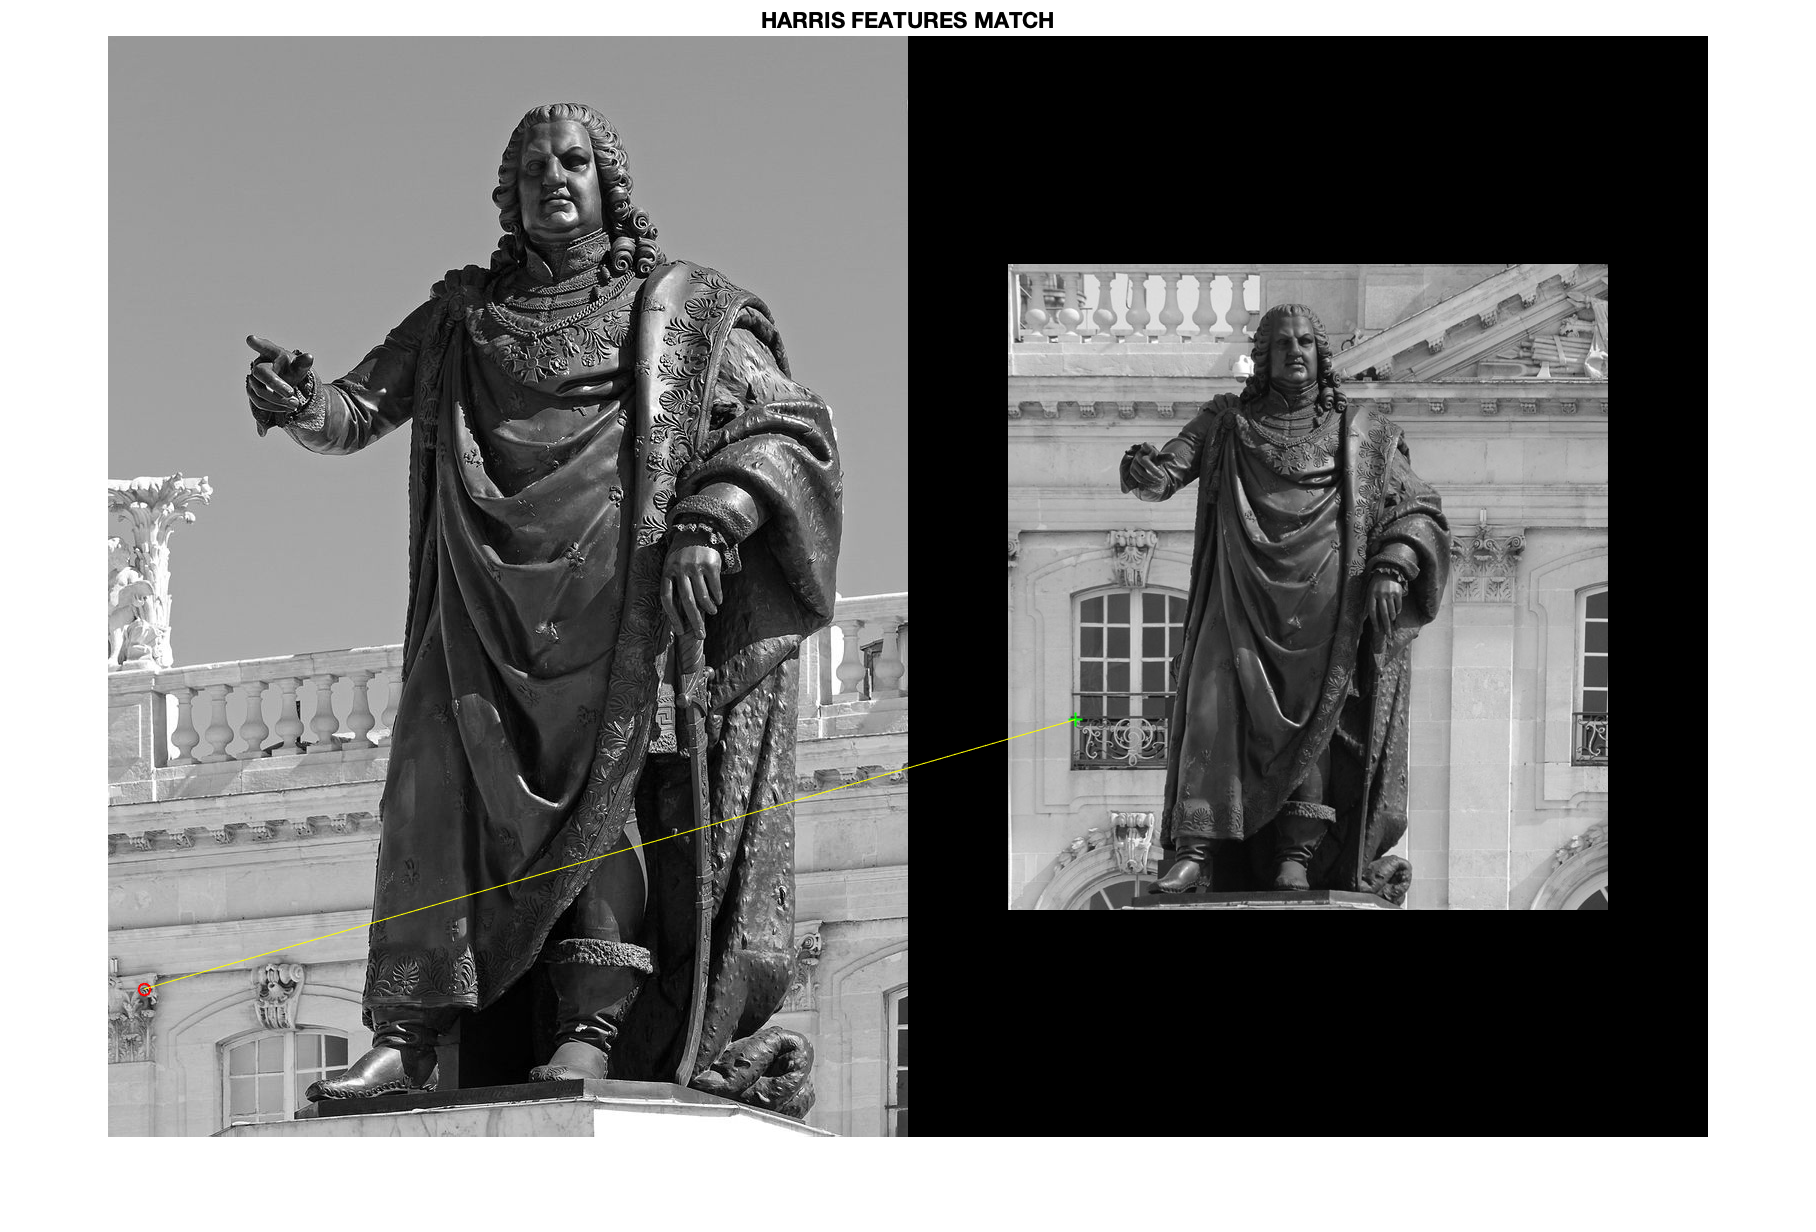

corners1 = detectHarrisFeatures(grayStanislasFace);
corners2 = detectHarrisFeatures(grayStanislasFace2);

%imshow(StanislasFace),title('Corners of StanislasFace'); hold on;
%plot(corners1);

%figure;imshow(StanislasFace2),title('Corners of StanislasFace 2'); hold on;
%plot(corners2);

%%%% Matching features using HARRIS POINTS
[features1,validPoints1] = extractFeatures(grayStanislasFace,corners1);
[features2,validPoints2] = extractFeatures(grayStanislasFace2,corners2);

indexPairs = matchFeatures(features1,features2,'MatchThreshold',100);
%%%% You can use the match threshold for selecting the strongest matches. 
%%%% The threshold represents a percent of the distance from a perfect match. 
%%%% The function rejects a match when the distance between the features is greater than the value of MatchThreshold

matchedPoints1 = validPoints1(indexPairs(:,1),:);
matchedPoints2 = validPoints2(indexPairs(:,2),:);

figure; showMatchedFeatures(grayStanislasFace,grayStanislasFace2,matchedPoints1,matchedPoints2,'montage'),title('HARRIS FEATURES MATCH');

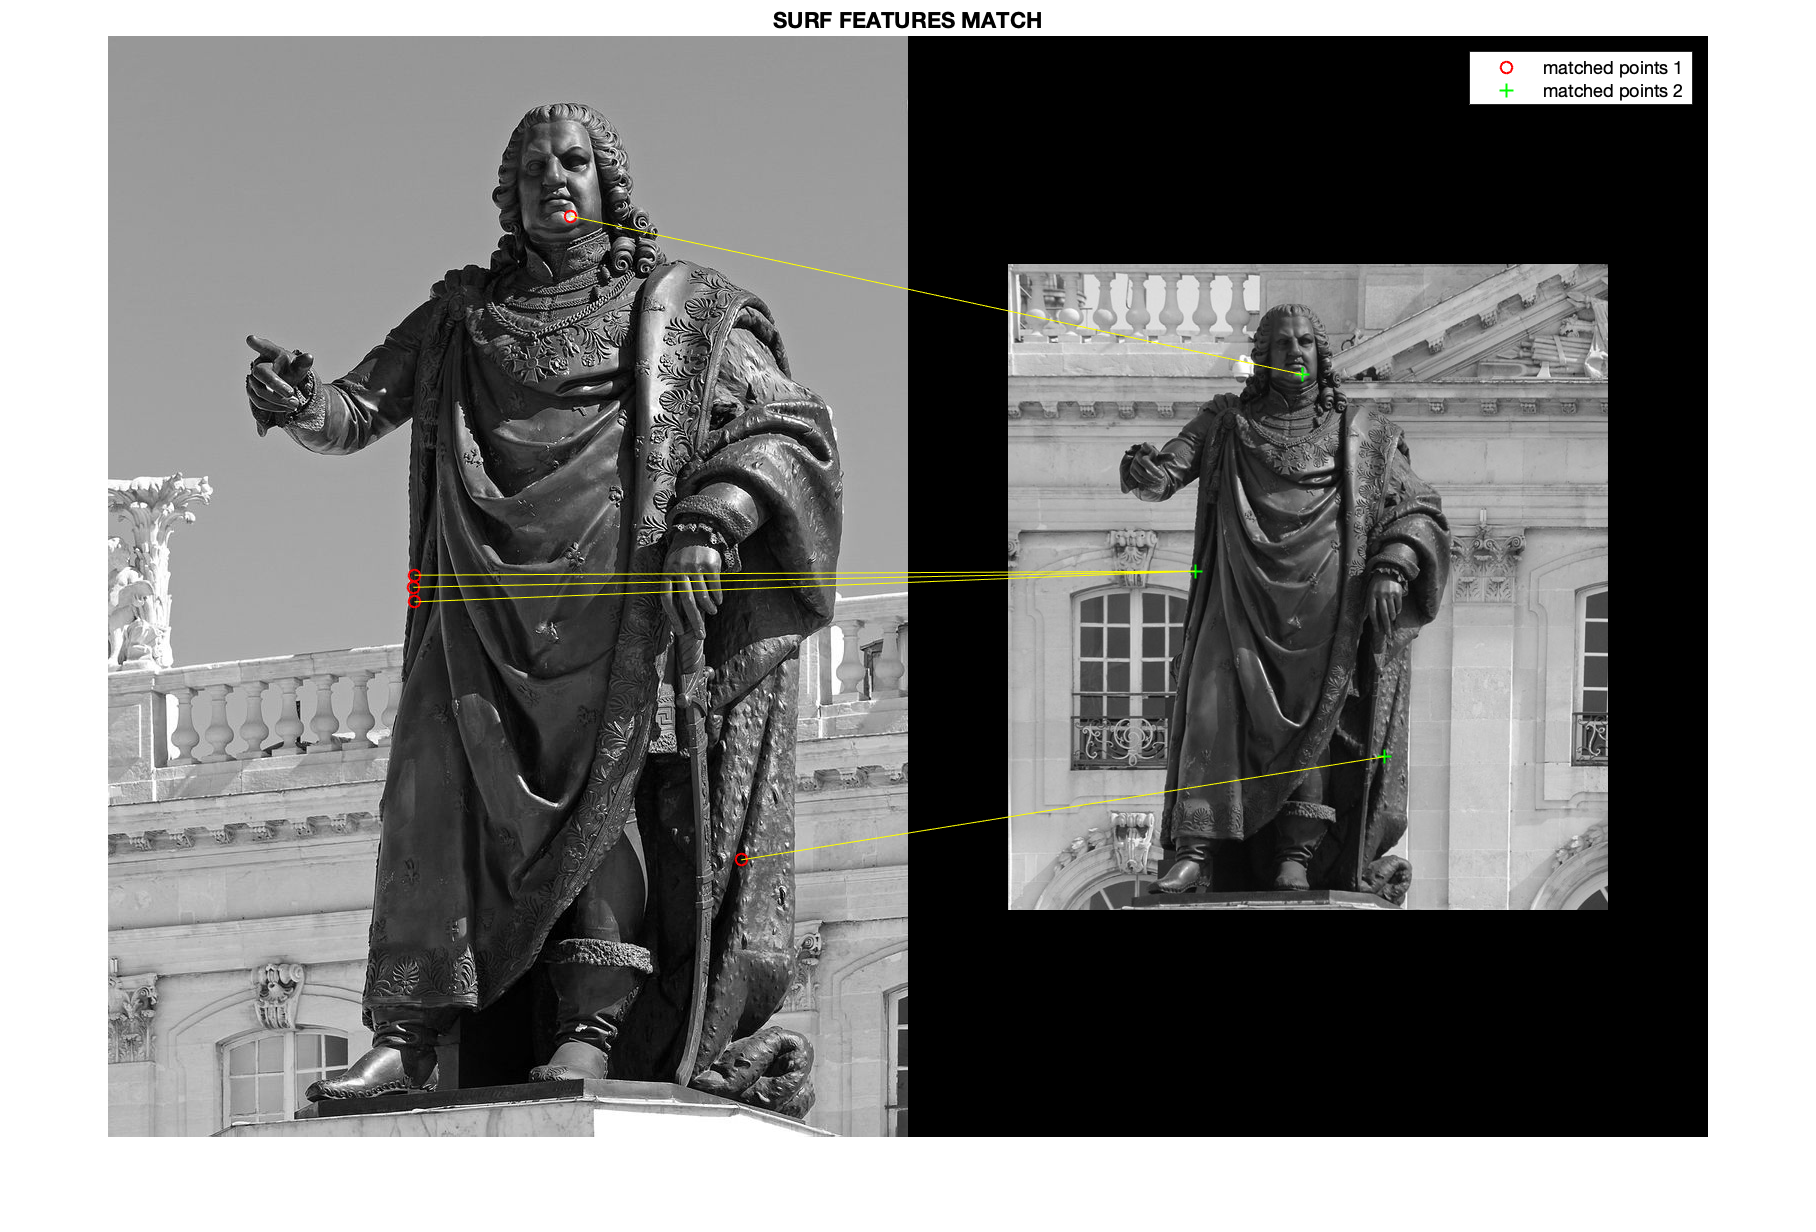


%%%% SURF FEATURES
points1 = detectSURFFeatures(grayStanislasFace);
points2 = detectSURFFeatures(grayStanislasFace2);

%imshow(StanislasFace),title('Corners of StanislasFace SURF'); hold on;
%plot(corners1);

%figure;imshow(StanislasFace2),title('Corners of StanislasFace 2 SURF'); hold on;
%plot(corners2);

[f1,vpts1] = extractFeatures(grayStanislasFace,points1);
[f2,vpts2] = extractFeatures(grayStanislasFace2,points2);

indexPairs = matchFeatures(f1,f2,'MatchThreshold',.5);
%%%% Added threshold to limit the most noticeable features

matchedPoints1 = vpts1(indexPairs(:,1));
matchedPoints2 = vpts2(indexPairs(:,2));
figure; showMatchedFeatures(grayStanislasFace,grayStanislasFace2,matchedPoints1,matchedPoints2,'montage'), title('SURF FEATURES MATCH');
legend('matched points 1','matched points 2');